clc; clear;
rng(1)

ns = 2;

ns = 2

points = 100;

points = 100


m1 = rand(ns,points);


x = string(char(randi(1,ns)));


deskripts(m1, x')

    Datanavn    Middelværdi    Varians     Standardafvigelse    Målepunkter
    ________    ___________    ________    _________________    ___________

      "□□"        0.44903      0.097494         0.31224             100    
      "□□"        0.52169      0.088403         0.29733             100    



Frihedsgradernes formel


$$\mathrm{df}=n_{1}+n_{2}-2$$

-----------------------------------------------------------------
Stikprøvemiddelværdiernes formel


$$\bar{y}=\frac{\Sigma \,y_{i}}{n}$$

-----------------------------------------------------------------
Stikprøvevariansernes formel


$$s=\frac{n\,\left(\Sigma \left({y_{i}}^{2}\right)-{\Sigma \left(y_{i}\right)}^{2}\right)}{n\,\left(n-1\right)}$$

-----------------------------------------------------------------
Pooled standardafvigelsens formel


$$s_{p}=\sqrt{\frac{\left(n_{1}-1\right)\,{s_{1}}^{2}+\left(n_{2}-1\right)\,{s_{2}}^{2}}{n_{1}+n_{2}-2}}$$

-----------------------------------------------------------------
t-værdiens formel


$$\frac{t_{\mathrm{df},\alpha }}{2}=-\mathrm{tinv}\,\frac{\alpha }{2}\,\mathrm{df}$$

-----------------------------------------------------------------
Teststørrelsens formel


$$t_{\mathrm{val}}=\frac{y_{\mathrm{bar1}}-y_{\mathrm{bar2}}-\delta }{s_{p}\,\sqrt{\frac{1}{n_{1}}\,\frac{1}{n_{2}}}}$$

-----------------------------------------------------------------
    Datanavne    Middelværdier    Spredning    standardafv.    Datapunkter
    _________    _____________    _________    ____________    ___________

        a           0.44903       0.097494       0.31224           100    
        b           0.52169       0.088403       0.29733           100    

    Frihedsgrader    Pooled varians    Pooled spredning    Teststatistik      t0      p-værdi     h-værdi
    _____________    ______________    ________________    _____________    ______    ________    _______

         19

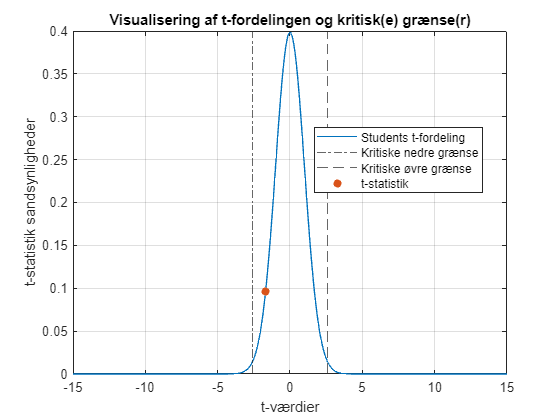

Da h = 0 forkastes nulhypotesen ikke
Ydermere ses det også at t-værdien -1.6851 ikke overstiger den kritiske grænse på 2.6009


ans = struct with fields:
    stats: [1×1 struct]
        p: 0.0936
       ci: [-0.1951 0.0497]



a = m1(1,:);
b = m1(2,:);

Studenttest2pop(a,b, "both", 99, 0)